# Recursive Least Squares estimation

## Introduction

### Purpose

The purpose of this notebook is to show the effectiveness of a recursive algorithm for the estimation of the admittance matrix.

Moreover, we aim at assessing the increase in accuracy and convergence speed achieved by properly parametrizing the admittance matrix, in order to remove redundant parameters.

### Method

We define a simple DC microgrid, with $n=4$ nodes, $n_l=2$ loads and $n_g=2
$ generators. Loads are modelled as ZIP, with a constant power, a constant current and a constant impedence component. For a generic load l, it holds $V_l = \bar I + \bar Y I_l + \frac{\bar P}{I_l}$. We also define the admittance matrix $Y$ of the grid. By construction, such $Y$ is Laplacian, that is symmetric, positive semidefinite and with zero row sum. A series of samples of generator voltages $V_g$ is than simulated, with each voltage modelled as a Gaussian random variable. From generator voltages, load voltages $V_l$ are derived using power flow equations. When more solutions are feasible, we always choose the high-voltage one. Finally, currents $I$ are derived by the relation $I = YV$, where $V = [V_g V_L]^T$.

Using samples of $I$ and $V$ as input, a rescursive least square algorithm is run in order to estimate $Y$. Three different flavours of the RLS are tested, differing in the number of free parameters:

- A naive verson (RLS1) assumes that the whole matrix $Y$ has to be estimated, resulting in $n^2$ free parameters. This approach is implemented by keeping $Y$ as a matrix.

- A vectorized version (RLS2) exploits the relies on the half-vectorization of $Y$, $vech(Y)$. By imposing a symmetric structure, the number of free parameters is reduced to $n(n+1)/2$ and, by exploiting vectorization, we can rely on the standard RLS formulae. However, the constraint on the row sum is not yet enforced. This is similar to the approach by Claire Tomlin [**1**]

- An enhanced vectorized version (RLS3) adopts a new form of vectorization which enforces both the symmetric structure and the zero row sum, thus further reducing the number of free parameters to $n(n-1)/2$. This approach is enabled by a novel algorithm to create a matrix $Q$ such that $vech(Y) = Q * v(Y)$, where $v(Y)$ is a vector containing only the free parameters of Y. Then, the well-known duplication matrix $D$ can be used to recover the full vectorization of $Y$ and thus whole matrix [**2**]. $vec(Y) = D * vech(Y) = D*Q*v(Y)$.

The speed of convergence and the accuracy of the estimates are evaluated, both visually and quantitavely. Let $\hat Y$ denote the estimated admittance matrix. The Frobenius norm and the max norm of the error matrix $E = |Y - \hat Y|
$ are used to assess the goodness of fit.

### Conclusion

- Due to the generative model, involving power flow equations, the voltage series are highly correlated. This is a problem for the RLS algorithm

- All the approaches (RLS1, RLS2, RLS3) are very sensitive to noise on current measurements, but decreasing the number of parameters help in containing the error

- RLS3 outperforms the other approaches with any level of noise, but more apparently when noise increases in magnitude

### Next Steps

- Improve and make more elegant the algorithm to build Q

- Find - if possible - a matrix costruction for Q - like in the paper about D [**2**]

- Test on an improved simulator (be careful about Sahel's suggestions!)

### Refrences

- Ardakanian - On Identification of Distribution Grids

- Jan R Magnus - The elimination matrix: Some lemmas and applications

- Luis A Escobar - A Note on the Updating of Regression Estimates

## Development

### Grid definition

Parameters for the grid are:

- the Laplacian admittance matrix $Y
$

- the load paramenters $\bar I
$, $\bar P$ and $\bar Y$

clear all
close all
rng default

I_bar = [15, 5]';
Y_bar = [0.01, 0.05]';
P_bar = [1200, 800]';
Y = [3 0 -2 -1; 0 2 -1 -1; -2 -1 3 0; -1 -1 0 2];
n = length(Y); % nodes
nl = length(Y_bar); % loads
ng = n - nl; % generators

### Sample collection

We simulate generator voltages as incorrelated random variables, oscillating around a mean value, and we compute load voltages using power flow equations. Then, we build voltages using the equation $I = YV + e$, where $e$ is gaussian noise, with arbitrary variance. We take a variable number of samples for currents and voltages, 100 by default.

samples = 100;
Vg = normrnd(200, 2.5, ng, samples);
Vl = zeros(nl, samples);
for i = 1:samples
    Vl(:, i) = load_voltages_from_generator_voltages(Vg(:, i), I_bar, Y_bar, P_bar, Y);
end
V = [Vg; Vl];
% V = normrnd(200, 10, n, samples);
I_clean = Y * V;
e = normrnd(0, 0.05, n, samples); % Very little noise
I = I_clean + e;

#### Balance check

We check that the power flow equations are always satisfied, in order to certify the goodness of the data

I_check = zeros(nl, samples);
P_check = zeros(nl, samples);
for i = 1:samples
    P_check = fg(Vg(:, i), Vl(:, i), Vg(:, i).*I_clean(1:ng, i), Y);
    I_check = fl(Vg(:, i), Vl(:, i), I_bar, Y_bar, P_bar, Y);
end
max(abs(P_check))

ans = 1.5461e-11

max(abs(I_check))

ans = 6.6613e-14

We also check the correlation between voltages

corr(V')

ans =     1.0000   -0.0243    0.8918    0.6975
   -0.0243    1.0000    0.4306    0.6994
    0.8918    0.4306    1.0000    0.9462
    0.6975    0.6994    0.9462    1.0000


### Naive Recursive Least Square (RLS1)

We implement a recursive least square (RLS) estimator for $Y$, with a forgetting factor $\lambda$. However, we do not take into account the structure of the admittance matrix. Thus, the Laplacian is not assured to be symmetric nor to have a zero-row sum and the number of paramters to estimate is $n^2$, where $n$ is the number of nodes (generator and loads) in the network. Arbitrary initial guesses for both the admittance matrix and the variance of its parameters must be provided. 

lambda = 0.9;
Y1_hat = [];
Y1_hat(:, :, 1) = 0.1 * ones(n);
Z1 = [];
Z1(:, :, 1) = 100 * eye(n);
for i = 2:samples
    Z1(:, :, i) = (1/lambda) * (Z1(:, :, i-1) - Z1(:, :, i-1) * V(:, i) * inv(lambda + V(:, i)' * Z1(:, :, i-1) * V(:, i)) * V(:, i)' * Z1(:, :, i-1));
    Y1_hat(:, :, i) = Y1_hat(:, :, i-1) + (I(:, i) - Y1_hat(:, :, i-1) * V(:, i)) * V(:, i)' * Z1(:, :, i);
end

We first check the final results

Y1_hat(:, :, end)

ans =     3.1349    3.6246    8.3831  -15.4168
   -0.0759    0.8257   -4.2921    3.6321
   -1.9256    0.1962    6.3294   -4.6911
   -1.0668    0.1710    3.6897   -2.8799


Z1(:, :, end)

ans = 	1.0e+06 *

    0.0003    0.0059    0.0167   -0.0233
    0.0059    0.1219    0.3454   -0.4825
    0.0167    0.3454    0.9788   -1.3671
   -0.0233   -0.4825   -1.3671    1.9095


### Recursive Least Square with half-vectorization (RLS2)

Next, we implement a RLS where the parameters are the half-vectorization of the matrix Y. This drops the number of free parameters to $n(n+1)/2$ but does not ensure the zero-row-sum property.

rls2_free_params = n*(n+1)/2;
y_hat = [];
y_hat(:, 1) = 0.1 * ones([rls2_free_params, 1]);
Z2 = [];
Z2(:, :, 1) = 100 * eye(rls2_free_params);
D = duplication_matrix(n);
Y2_hat = [];
Y2_hat(:, :, 1) = reshape(D * y_hat(:, 1), [n n]);
for i = 2:samples
    a = kron(V(:, i), eye(n))' * D;
    Z2(:, :, i) = (1/lambda) * (Z2(:, :, i-1) - Z2(:, :, i-1) * a' * inv(lambda * eye(n) + a * Z2(:, :, i-1) * a') * a * Z2(:, :, i-1));
    y_hat(:, i) = y_hat(:, i-1) + Z2(:, :, i) * a' * (I(:, i) - a * y_hat(:, i-1));
    Y2_hat(:, :, i) = reshape(D * y_hat(:, i), [n n]);
end

We check the results

Y2_hat(:, :, end)

ans =     3.0011    0.0149   -1.9573   -1.0598
    0.0149    1.9007   -1.3522   -0.5562
   -1.9573   -1.3522    1.8220    1.5129
   -1.0598   -0.5562    1.5129    0.0712


Z2(:, :, end)

ans = 	1.0e+06 *

    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0001    0.0001   -0.0002    0.0002
    0.0000    0.0000    0.0000   -0.0001    0.0003    0.0009   -0.0012    0.0024   -0.0034    0.0048
   -0.0000    0.0000    0.0001   -0.0002    0.0009    0.0025   -0.0034    0.0069   -0.0097    0.0135
   -0.0000   -0.0001   -0.0002    0.0002   -0.0012   -0.0034    0.0048   -0.0097    0.0135   -0.0189
    0.0000    0.0003    0.0009   -0.0012    0.0063    0.0179   -0.0250    0.0507   -0.0708    0.0989
    0.0000    0.0009    0.0025   -0.0034    0.0179    0.0507   -0.0708    0.1436   -0.2006    0.2802
   -0.0001   -0.0012   -0.0034    0.0048   -0.0250   -0.0708    0.0989   -0.2006    0.2802   -0.3914
    0.0001    0.0024    0.0069   -0.0097    0.0507    0.1436   -0.2006    0.4070   -0.5684    0.7939
   -0.0002   -0.0034   -0.0097    0.0135   -0.0708   -0.2006    0.2802   -0.5684    0.7939   -1.1089
    0.0002    0.0048    0.0135   -0.0189    0.0989    0.2802   -0.3914   

## Recursive Least Square without redundant parameters (RLS3)

Then, we implement a similar RLS algorithm which takes into account the constraints on the Laplacian admittance matrix and thus reduces the number of free parameters from to $n(n-1)/2$.

rls3_free_params = n*(n-1)/2;
x_hat = [];
x_hat(:, 1) = 0.1 * ones([rls3_free_params, 1]);
Z3 = [];
Z3(:, :, 1) = 100 * eye(rls3_free_params);
Q = D * transformation_matrix(n);
Y3_hat = [];
Y3_hat(:, :, 1) = reshape(Q * x_hat(:, 1), [n n]);
for i = 2:samples
    a = kron(V(:, i), eye(n))' * Q;
    Z3(:, :, i) = (1/lambda) * (Z3(:, :, i-1) - Z3(:, :, i-1) * a' * inv(lambda * eye(n) + a * Z3(:, :, i-1) * a') * a * Z3(:, :, i-1));
    x_hat(:, i) = x_hat(:, i-1) + Z3(:, :, i) * a' * (I(:, i) - a * x_hat(:, i-1));
    Y3_hat(:, :, i) = reshape(Q * x_hat(:, i), [n n]);
end

We check the results:

Y3_hat(:, :, end)

ans =     2.9811    0.0045   -1.9232   -1.0623
    0.0045    1.9987   -1.0222   -0.9810
   -1.9232   -1.0222    2.6975    0.2479
   -1.0623   -0.9810    0.2479    1.7955


Z3(:, :, end)

ans =     0.0397    0.4060   -0.3339   -0.1294    0.1058    1.2948
    0.4060    4.9804   -4.1031   -1.5787    1.3008   15.9137
   -0.3339   -4.1031    3.3813    1.3006   -1.0719  -13.1125
   -0.1294   -1.5787    1.3006    0.5037   -0.4147   -5.0296
    0.1058    1.3008   -1.0719   -0.4147    0.3423    4.1441
    1.2948   15.9137  -13.1125   -5.0296    4.1441   50.9469


## Recursive Least Square with Optimal Experiment Design (RLS4)

Finally, we take our best algorithm until now and we make it active. Through Optimanl Design of Experiment (ODE) aka Active Learning, we aim at choosing, at each iteration, the generator voltages which let us get the most information about the unknown parameters, according to our best estimate until that iteration.

In our RLS setting, this translates to finding the generator voltages to feed the network as:


$$V_g^\star = \arg \min_{V_g}f(Var[v(Y)])$$


subject to power flow and technical constraints, where $f$ is a scalar-valued function of the covariance matrix $Var[v(Y)]$ of the non-redundant vectorization of the admittance matrix $Y$. 

x_ode_hat = [];
x_ode_hat(:, 1) = 0.1 * ones([rls3_free_params, 1]);
Z_ode = [];
Z_ode(:, :, 1) = 100 * eye(rls3_free_params);
Y_ode_hat = [];
Y_ode_hat(:, :, 1) = reshape(Q * x_ode_hat(:, 1), [n n]);
V_star_ode = [];
V_real_ode = [];
x0 = mean(V, 2);
lb = min(V, [], 2);
ub = max(V, [], 2);
for i = 2:samples
    f = @(x) - log(det(inv(Z_ode(:, :, i-1)) + (kron(x, eye(n))' * Q)' * (kron(x, eye(n))' * Q)));
    cons = @(x) fl_constraint(x(1:ng), x(ng+1:end), I_bar, Y_bar, P_bar, Y_ode_hat(:, :, i-1));
    
    V_star_ode(:, i) = fmincon(f, x0, [], [], [], [], lb, ub, cons);
    
    V_real_ode(:, i) = [V_star_ode(1:ng, i); load_voltages_from_generator_voltages(V_star_ode(1:ng, i), I_bar, Y_bar, P_bar, Y)];
    I_real_ode(:, i) = Y * V_real_ode(:, i) + e(:, i);
    
    a = kron(V_real_ode(:, i), eye(n))' * Q;
    Z_ode(:, :, i) = (1/lambda) * (Z_ode(:, :, i-1) - Z_ode(:, :, i-1) * a' * inv(lambda * eye(n) + a * Z_ode(:, :, i-1) * a') * a * Z_ode(:, :, i-1));
    x_ode_hat(:, i) = x_ode_hat(:, i-1) + Z_ode(:, :, i) * a' * (I_real_ode(:, i) - a * x_ode_hat(:, i-1));
    Y_ode_hat(:, :, i) = reshape(Q * x_ode_hat(:, i), [n n]);
end


Converged to an infeasible point.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance but constraints are not
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 


We check the results:

Y_ode_hat(:, :, end)

ans =     2.9971    0.0010   -1.9918   -1.0063
    0.0010    1.9980   -1.0012   -0.9978
   -1.9918   -1.0012    2.9691    0.0238
   -1.0063   -0.9978    0.0238    1.9803


Z_ode(:, :, end)

ans =     0.0058    0.0663   -0.0548   -0.0211    0.0173    0.2141
    0.0663    0.8207   -0.6770   -0.2596    0.2142    2.6478
   -0.0548   -0.6770    0.5591    0.2143   -0.1769   -2.1855
   -0.0211   -0.2596    0.2143    0.0827   -0.0680   -0.8379
    0.0173    0.2142   -0.1769   -0.0680    0.0565    0.6914
    0.2141    2.6478   -2.1855   -0.8379    0.6914    8.5543


## Goodness of fit

### Matrix elements

We check the evolution of the estimated admittance matrix Y with each algorithm

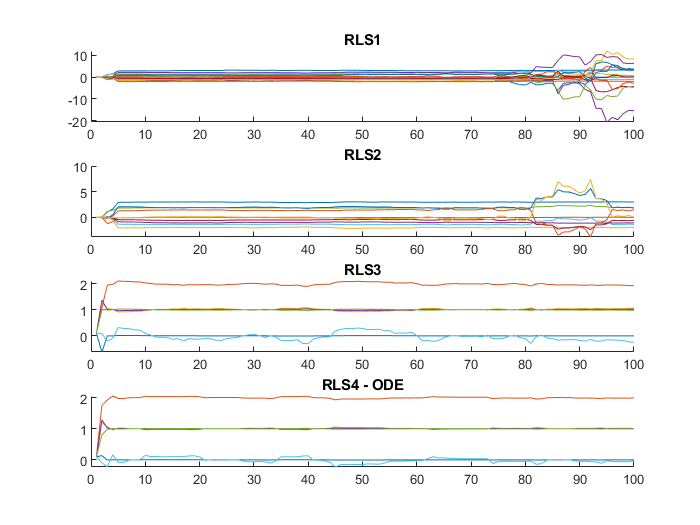

subplot(4, 1, 1);
hold on
for i=1:n
    for j=1:n
        plot(1:samples, squeeze(Y1_hat(i, j, :)));
    end
end
title('RLS1');
hold off
subplot(4, 1, 2);
hold on
for i=1:rls2_free_params
    plot(1:samples, squeeze(y_hat(i, :)));
end
title('RLS2');
hold off
subplot(4, 1, 3);
hold on
for i=1:rls3_free_params
    plot(1:samples, squeeze(x_hat(i, :)));
end
title('RLS3');
hold off
subplot(4, 1, 4);
hold on
for i=1:rls3_free_params
    plot(1:samples, squeeze(x_ode_hat(i, :)));
end
title('RLS4 - ODE');
hold off

### Error metrics

Finally, we resort to some error metrics to evaluate the goodness of fit. Error metrics are the Frobenius norm and the max norm of the matrix $Y_e = \left |Y - \hat Y \right|$.

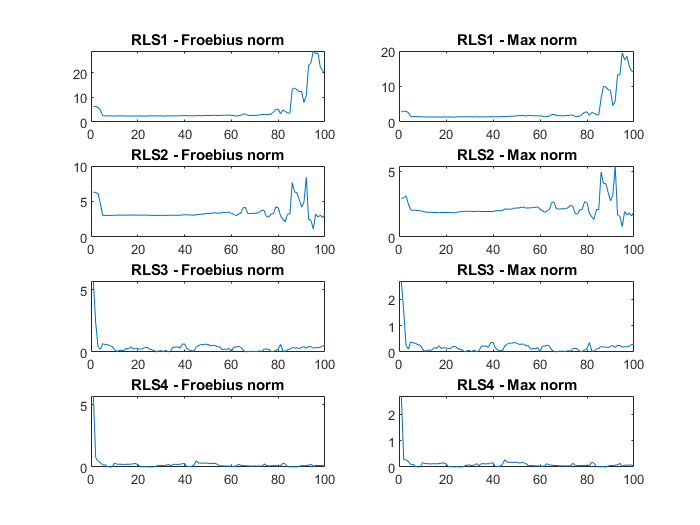

Ys_hat = {Y1_hat, Y2_hat, Y3_hat, Y_ode_hat};
for i=1:length(Ys_hat)
    Y_hat = cell2mat(Ys_hat(i));
    Ye = abs(Y_hat - Y);
    froeb_norm = [];
    max_norm = [];
    for j = 1:samples
        froeb_norm(j) = norm(Ye(:, :, j), 'fro');
        max_norm(j) = max(max(Ye(:, :, j)));
    end
    subplot(length(Ys_hat), 2, 2*i - 1);
    plot(1:samples, squeeze(froeb_norm));
    title(['RLS' num2str(i) ' - Froebius norm']);
    subplot(length(Ys_hat), 2, 2*i);
    plot(1:samples, squeeze(max_norm));
    title(['RLS' num2str(i) ' - Max norm']);
end